LBW_st.name='LBW';
LBW_st.lat=43.1482;
LBW_st.lon=-73.1268;
LBW_st.alt=1015;


LBW_rd=read_betsy('LBW_head',LBW_st.name);

datevec(LBW_rd.Time(1))

ans =         1993           7           2           0           0           0

datevec(LBW_rd.Time(end))

ans =         2004           1           1           0           0           0

prctile(LBW_rd.U_S,[5 50 95])

ans =    54.8353   84.0200  100.0217

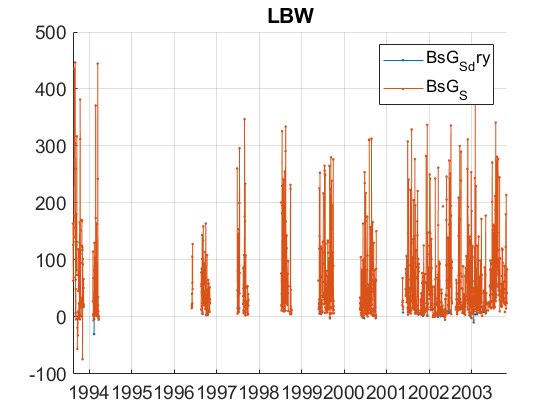

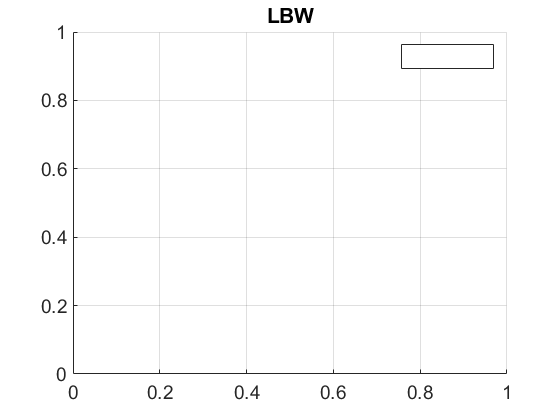

plotFigControl(LBW_rd,LBW_st.name);

% 1 size cut, 
% sc: ok, no clear seasonal cycle, few negatives
%with RH<50 really almost no  data


% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE=[467;529;653]*ones(1,4);
% LBW_cal=compute_exp_SSA(LBW_rd,lambdaSC, lambdaAE);
% plotFigControl_cal(LBW_cal,LBW_cal.name);

%Questions:
%problems:
% no data from mid 1994 to 1997 + a lot of holes


LBW_t=timetable(LBW_rd.Time);
%scat  begin at the beginning of a year: 1994
%end 2003
% neph and abs PM1 to remove
%remove N